# [Steel Plate Defects](https://apmonitor.com/pds/index.php/Main/SteelPlateFaults)

**Background**

 [Steel plate defects](https://apmonitor.com/pds/uploads/Main/steel.txt) are extracted from photos of several faulty steel plates with surface imperfections. Image analysis revealed 27 different features to describe the steel fault. A total of 6 unique types of faults are categorized, with a final category of "other faults" for any type of fault that does not fit into the other specific 6 categories.

% Import data
url = 'http://apmonitor.com/pds/uploads/Main/steel.txt';
data = readtable(url);

% Rename the variables
parameters = ["X Minimum" "X Maximum" "Y Minimum"...
            "Y Maximum" "Pixels Areas" "X Perimeter" ...
            "Y Perimeter" "Sum of Luminosity" "Minimum of Luminosity"...
            "Maximum of Luminosity" "Length of Conveyer" "Type of Steel A300"...
            "Type of Steel A400" "Steel Plate Thickness" "Edges_Index" ...
            "Empty Index" "Square Index" "Outside X Index"...
            "Edges X Index" "Edges Y Index" "Outside Global Index"...
            "Log of Areas" "Log X Index" "Log Y Index" ...
            "Orientation Index" "Luminosity Index" "Sigmoid of Areas"...
            "Pastry" "Z Scratch" "K Scratch" "Stains" "Dirtiness"...
            "Bumps" "Other Faults"];
data.Properties.VariableNames = parameters;

% Display a sample of the data
head(data);

    X Minimum    X Maximum    Y Minimum     Y Maximum     Pixels Areas    X Perimeter    Y Perimeter    Sum of Luminosity    Minimum of Luminosity    Maximum of Luminosity    Length of Conveyer    Type of Steel A300    Type of Steel A400    Steel Plate Thickness    Edges_Index    Empty Index    Square Index    Outside X Index    Edges X Index    Edges Y Index    Outside Global Index    Log of Areas    Log X Index    Log Y Index    Orientation Index    Luminosity Index    Sigmoid of Areas    Pastry    Z Scratch<

% Display the size of the data
disp(size(data))

        1941          34



**Features**

There are 27 features that are used to predict the steel faults. These features are extracted from steel plate samples. Computer vision can automatically extract some of this information from images or manually extracted with a user inspecting each plate defect or photo of the steel plate.

- X_Minimum

- X_Maximum

- Y_Minimum

- Y_Maximum

- Pixels_Areas

- X_Perimeter

- Y_Perimeter

- Sum_of_Luminosity

- Minimum_of_Luminosity

- Maximum_of_Luminosity

- Length_of_Conveyer

- TypeOfSteel_A300

- TypeOfSteel_A400

- Steel_Plate_Thickness

- Edges_Index

- Empty_Index

- Square_Index

- Outside_X_Index

- Edges_X_Index

- Edges_Y_Index

- Outside_Global_Index

- LogOfAreas

- Log_X_Index

- Log_Y_Index

- Orientation_Index

- Luminosity_Index

- SigmoidOfAreas

**Labels:** There are 7 types of steel plate defects that are labelled with a 1 if present and 0 if not present with [One-Hot Encoding](https://apmonitor.com/pds/index.php/Main/FeatureEngineering). A unique aspect of this data set is that the labels are imbalanced, meaning that there is a large difference in the number of specific defects.

- Pastry

- Z_Scratch

- K_Scatch

- Stains

- Dirtiness

- Bumps

- Other_Faults

In cases where there is a large imbalance, a strategy is to [synthetically generate new data sets to improve the balance](https://machinelearningmastery.com/multi-class-imbalanced-classification/). That strategy is not taken in this case study but could be an option to improve the classification training. The fault label is not stored as a sequential value (e.g. fault label as 0-6) but is [One-hot encoded](https://en.wikipedia.org/wiki/One-hot) to translate the fault label into a binary representation (0 or 1) for each fault. There are 7 additional columns of data with 1 if the fault exists and 0 if the fault does not exist.

## Detect Outliers

Detect outliers and remove bad data if present.

% Get the names of the input variables
features = parameters(1:27)

features = 1×27 string array
    "X Minimum"    "X Maximum"    "Y Minimum"    "Y Maximum"    "Pixels Areas"    "X Perimeter"    "Y Perimeter"    "Sum of Luminosity"    "Minimum of Luminosity"    "Maximum of Luminosity"    "Length of Conveyer"    "Type of Steel A300"    "Type of Steel A400"    "Steel Plate Thickness"    "Edges_Index"    "Empty Index"    "Square Index"    "Outside X Index"    "Edges X Index"    "Edges Y Index"    "Outside Global Index"    "Log of Areas"    "Log X Index"    "Log Y Index"    "Orientation Index"    "Luminosity Index"    "Sigmoid of Areas"


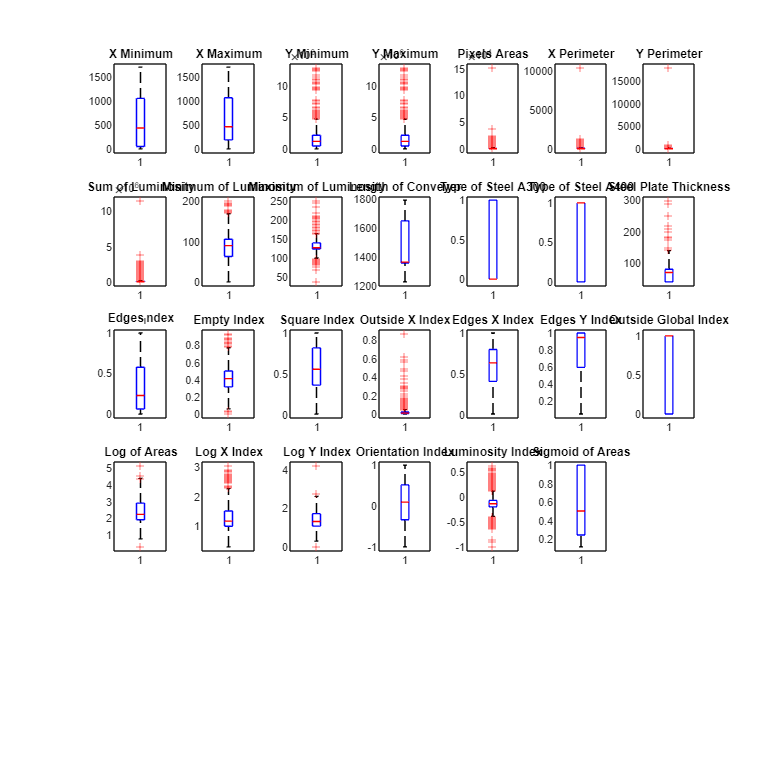


% Create a figure
figure;
set(gcf, 'Position', [100,100,2000,2000])

% Make a boxplot of each feature 
for i = 1:numel(features)
    subplot(5, 7, i);
    boxplot(data.(features{i}));
    title(features{i}, "FontSize", 9);
end

**Data Exploration**

Generate summary statistics with a profiling report to [statistically characterize the data](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify any outliers in the data. Remove any outliers from the data set. What factors are highly correlated to the steel faults? Generate a bar chart that shows the imbalance of faults in the data.

% Get the labels of the different defect types
labels = data(:,28:end).Properties.VariableNames

labels = 1×7 cell array
    {'Pastry'}    {'Z Scratch'}    {'K Scratch'}    {'Stains'}    {'Dirtiness'}    {'Bumps'}    {'Other Faults'}


% Sort all feature data into X and all label data into y
X = data(:,1:27);
y = data(:,28:end);

% Count the number of defects under each label
counts = varfun(@groupcounts,y,"InputVariables",labels);
counts = counts(2,:)

counts = 1×7 table
    groupcounts_Pastry    groupcounts_Z Scratch    groupcounts_K Scratch    groupcounts_Stains    groupcounts_Dirtiness    groupcounts_Bumps    groupcounts_Other Faults
    __________________    _____________________    _____________________    __________________    _____________________    _________________    ________________________

           158                     190                      391                     72                     55                     402                     673           


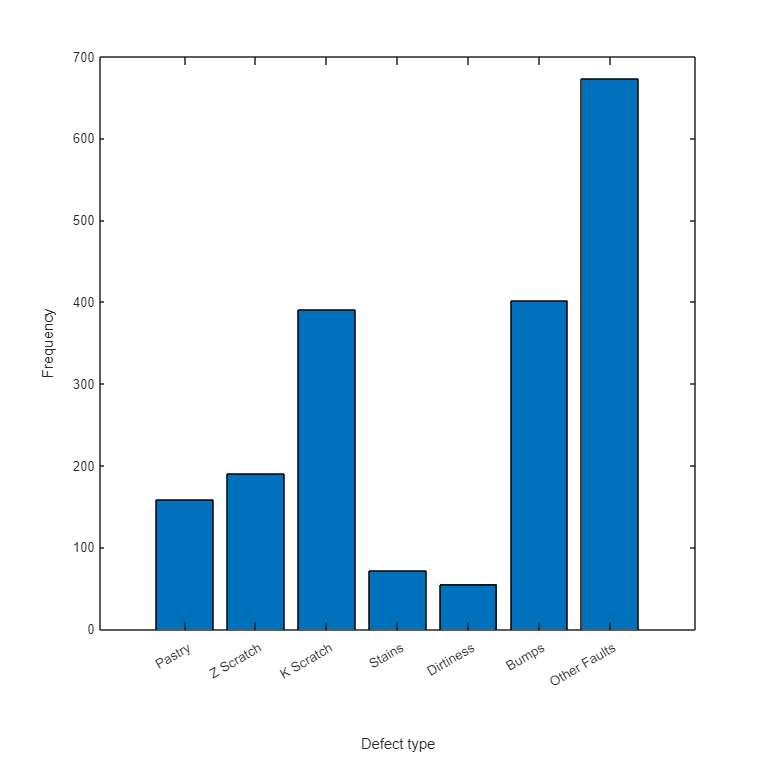

% Create a bar plot of the number of each defect
figure;
bar(table2array(counts))
set(gca,'XTick',1:length(labels),'XTickLabel',labels)
xlabel("Defect type")
ylabel("Frequency") 

## **Classification of Faults**

A classifier is an algorithm or model that categorizes input data based on its characteristics. The classifier then uses correlations or patterns in the input data to categorize or label unseen or future data. In this case our classifer is a neural network, our input data is the training set, and our unseen data is the test set. A neural network consists of multiple layers that receive data, perform mathematical computations, and produce a final output. The final output is compared with the desired output and the neural network ajdusts variables to minimize the error. 

Train and test a classifier to distinguish between steel plate faults.

Randomly select values that split the data into a train (80%) and test (20%) set.

% Get variable names for features and labels
features = data.Properties.VariableNames(1:end-7);
labels = data.Properties.VariableNames(end-6:end);

Xs = normalize(X); % Normalize features
rng("default") % For reproducibility of the data partition

c = cvpartition(height(data),"Holdout",0.20); % Create variable to partition the data
trainingIdx = training(c); % Training set indices
X_train = Xs(trainingIdx,:);
y_train = y(trainingIdx,:);
testIdx = test(c); % Indices for the test set
X_test = Xs(testIdx,:);
y_test = y(testIdx,:);

**Select Best Features**

Select the best features for the classification.

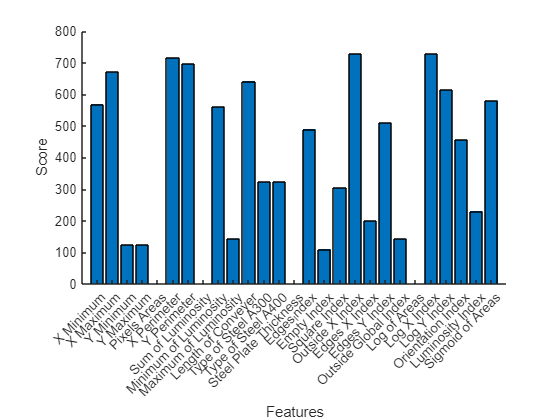

X_s = table2array(data(:,features)); % Get feature data in an array 
y_s = table2array(data(:,labels)); % Get label data in an array
y_scat = onehotdecode(y_s, labels, 2); % One hot decode the label data to a categorical representation

[fit, scores] = fscchi2(X_s, y_scat); % Find the association between features and defects using a chi-square test

% Visualize feature scores
bar(scores)
set(gca, 'XTick', 1:length(features), 'XTickLabel', features)
xlim([0 length(features)+1])
xlabel('Features')
ylabel('Score')
box off

Determine any evidence of overfitting by plotting the training and test (validation) loss functions by epoch.

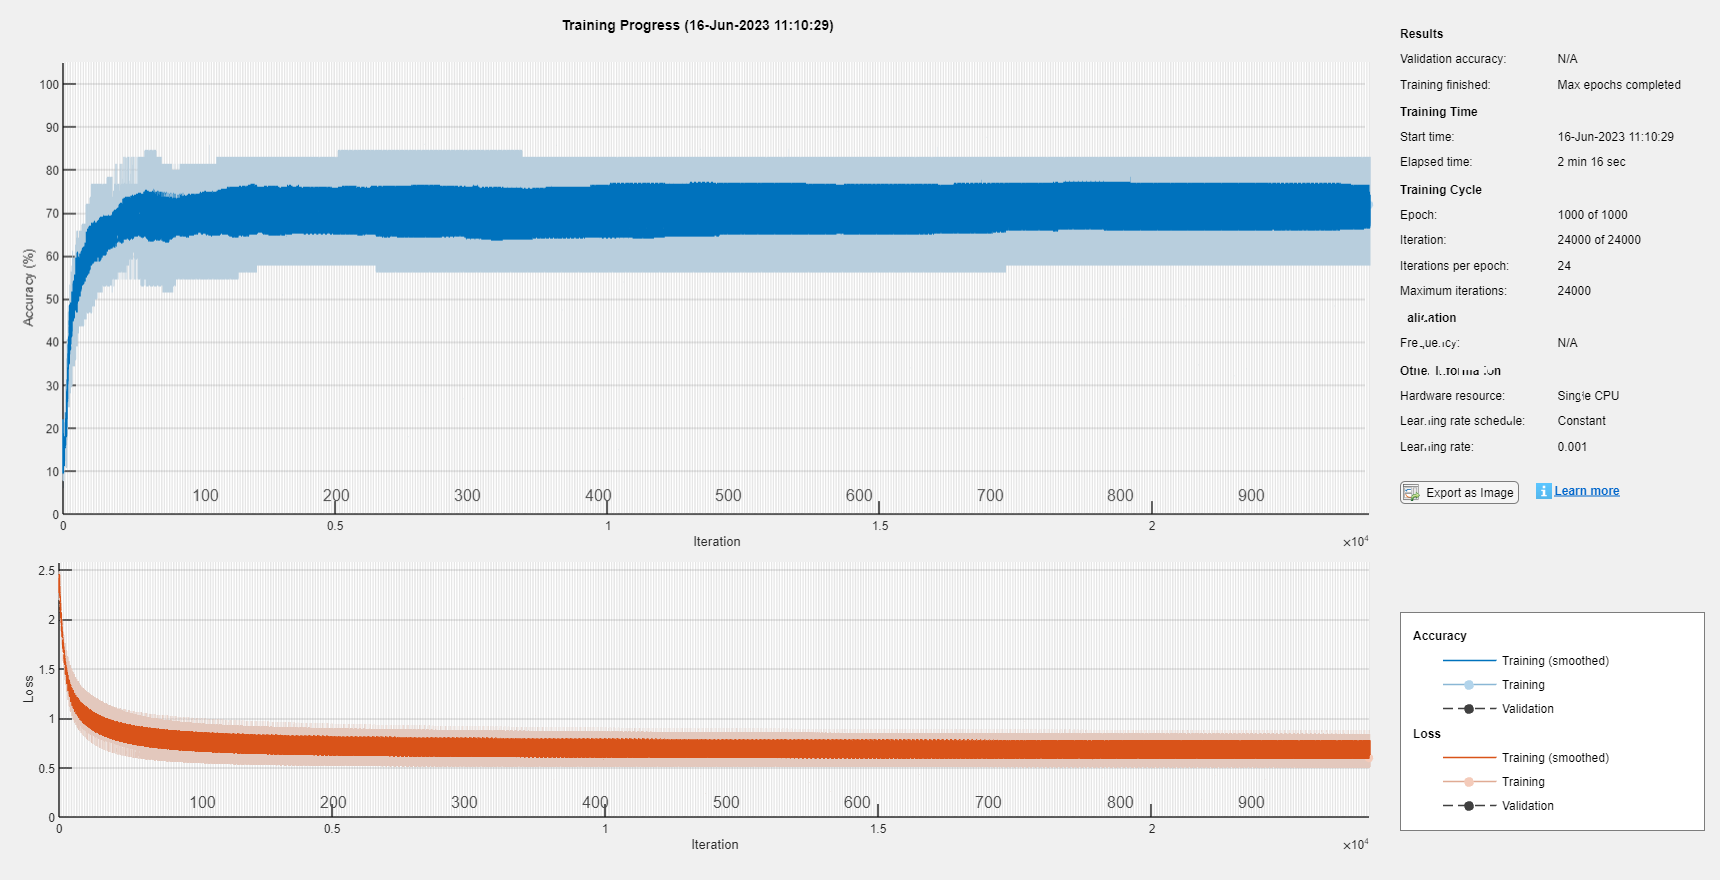

y_cat = onehotdecode(table2array(y_train), labels, 2); % Get categorical data
X_train_ar = table2array(X_train); % Convert the feature training data to an array

% Define the architecture for the neural network
layers = [ ...
    featureInputLayer(width(X_train))
    reluLayer
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

% Define training options for the neural network
options = trainingOptions('adam', ...  % adam is an optimization algorithm
    'MaxEpochs',1000,...  % An epoch is a cycle through the entire training set
    'InitialLearnRate',0.001, ...  
    'SquaredGradientDecayFactor',0.99,...
    'MiniBatchSize',64,...  % Divides the training subset into smaller subsets of 64
    'Verbose',false, ... % Verbose controls whether or not to display training progress information during training
    'Plots','training-progress');

% Train the neural network
[net,info] = trainNetwork(X_train_ar,y_cat,layers,options);

## Score and Accuracy

Neural network accuracy and loss are calculated by comparing the predicted outputs with the true labels. Accuracy is the proportion of correct predictions made by a neural network on a given set of data. Loss is a measure of the difference between the predicted outputs and the desired outputs on a given set of data. 

Calculate the score and accuracy of the nerual network.

A = info.TrainingAccuracy';
L = info.TrainingLoss'; 
nn_accuracy = mean(A(2500:end)) % Neural network accuracy

nn_accuracy = 71.5317

nn_loss = mean(L(2500:end)) % Neural network loss

nn_loss = 0.6913

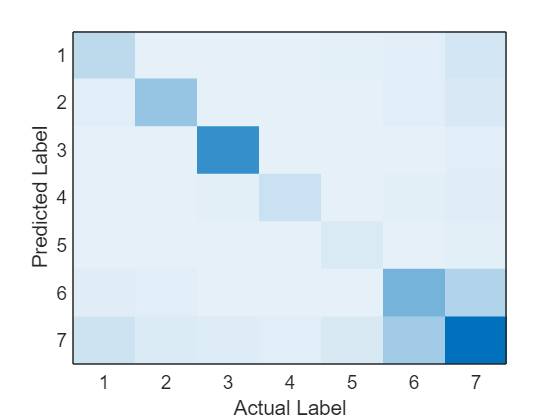


% Make predictions and save in table
yp = predict(net, X_train);
yp = array2table(yp, 'VariableNames', y_test.Properties.VariableNames);

% Extract predicted labels and probabilities
[~,predicted_label] = max(yp{:,:},[],2);
[~,actual_label] = max(y_train{:,:},[],2);

% Display probabilities, with the most likely label highlighted and the actual label displayed
yp_ActualFault = categorical(actual_label);

% Plot the confusion matrix
figure;
cm = confusionmat(predicted_label, actual_label);
heatmap(cm, 'ColorbarVisible', 'off', 'GridVisible', 'off', 'FontSize', 14, 'XLabel', 'Actual Label', 'YLabel', 'Predicted Label', 'CellLabelColor', 'none');

## Create Classifier Models

y_cat_test = onehotdecode(table2array(y_test), labels, 2);

% make models that use different classification methods
nb = fitcnb(X_train, y_cat);
nb_test = fitcnb(X_test, y_cat_test);
dt = fitctree(X_train, y_cat);
dt_test = fitctree(X_test, y_cat_test);
knn = fitcknn(X_train, y_cat);
knn_test = fitcknn(X_test, y_cat_test);
svm = fitcecoc(X_train, y_cat);
svm_test = fitcecoc(X_test, y_cat_test);
nn = fitcnet(X_train, y_cat, 'Standardize', true, 'LayerSizes', 10);
nn_test = fitcnet(X_test, y_cat_test, 'Standardize', true, 'LayerSizes', 10);
rfm = TreeBagger(50, X_train, y_cat, 'OOBPrediction','on');
rfm_test = TreeBagger(50, X_test, y_cat_test, 'OOBPrediction','on');

% calculate the loss as a measure of accuracy for each method
L_nb = loss(nb, X_train, y_cat);
L_nb_test = loss(nb_test, X_test, y_cat_test);

L_dt = loss(dt, X_train, y_cat);
L_dt_test = loss(dt_test, X_test, y_cat_test);

L_knn = loss(knn, X_train, y_cat);
L_knn_test = loss(knn_test, X_test, y_cat_test);

L_svm = loss(svm, X_train, y_cat);
L_svm_test = loss(svm_test, X_test, y_cat_test);

L_nn = loss(nn, X_train, y_cat);
L_nn_test = loss(nn_test, X_test, y_cat_test);

L_rfm = oobError(rfm);
L_rfm = L_rfm(end,:);
L_rfm_test = oobError(rfm_test);
L_rfm_test = L_rfm_test(end,:);

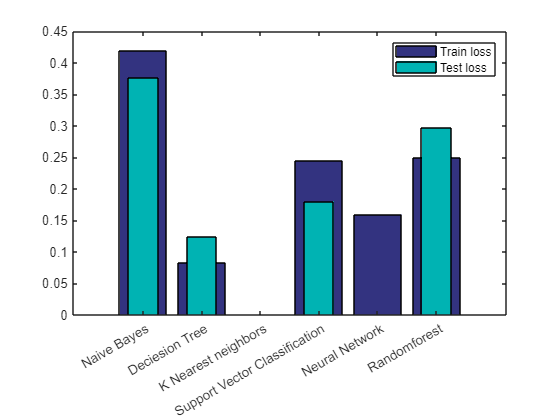

x = [1,2,3,4,5,6];
xtl = {'Naive Bayes'; 'Deciesion Tree'; 'K Nearest neighbors'; 'Support Vector Classification'; 'Neural Network'; 'Randomforest'};
train_loss = [L_nb, L_dt, L_knn, L_svm, L_nn, L_rfm ];
test_loss = [L_nb_test, L_dt_test, L_knn_test, L_svm_test, L_nn_test, L_rfm_test];

% Plot losses for each method
figure;
bar(x,train_loss,'FaceColor',[0.2 0.2 0.5])
scalebar = 0.5;
hold on
bar(x,test_loss,scalebar,'FaceColor',[0 0.7 0.7])
legend('Train loss', 'Test loss')
hold off
xticklabels(xtl);